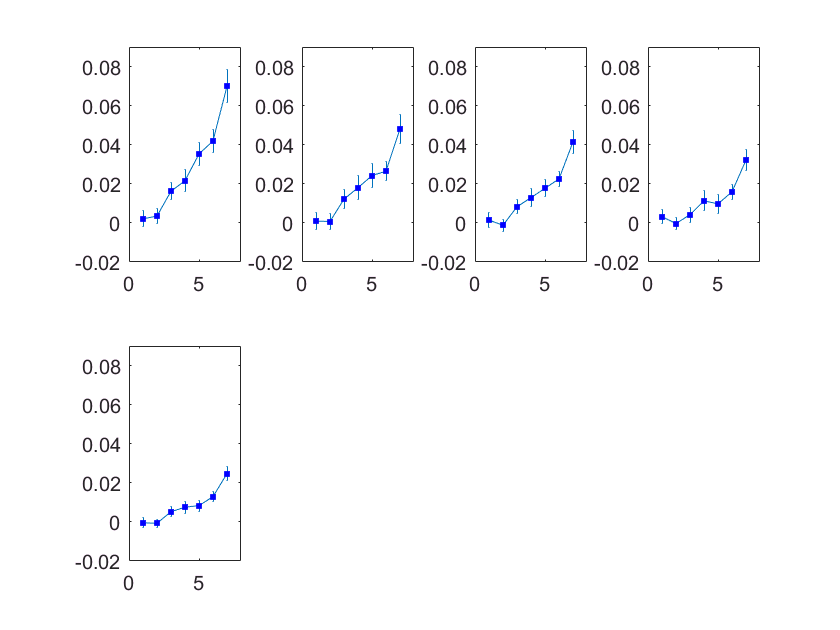

% CRF over frames 14-16

% time point = 1.5 seconds, based on latency figs
% 1 frames = 0.1 sec, so 1.5 secs = frame 15

frameRange = 14:16;
contrastValues = [0 0.03 0.063 0.125 0.25 0.5 1];

figure 
% suptitle 
for i = 1:length(xpts)
    
    clear sq5FramesOverTrialsPTSdfof
    clear meanOverFramesSq5FramesOverTrialsPTSdfof
    clear meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof
    clear contStdErr
    
    for c = 1:length(contrasts)
        clear trials
        trials =  abs(tcTrialMinusOne)==contrasts(c);
        
        % CRF POINTS for each contrast, i-th point
        % to use a range of frames (reduce noise):
        
        % take the i-th points over the frame range, for the c-th trials
        % returns 3 (frames) by 76 (trials)
        sq5FramesOverTrialsPTSdfof = squeeze(PTSdfof(i,frameRange,trials));
        
        % take the mean over frames
        %returns 1 x 76 (trials)
        meanOverFramesSq5FramesOverTrialsPTSdfof = mean(sq5FramesOverTrialsPTSdfof,1);
       
        % now I need the mean over trials to get one df/f value representing the
        % average fluorescence over 3 frames and over the c-th trials for the i-th point
        meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof = mean(meanOverFramesSq5FramesOverTrialsPTSdfof,2);
        
        % now I want to collect each c-th CRF value for this point
        % creates 1 x 7 (contrasts)
        contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof(c) = meanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof;
        
        % STDERR
        % now I want to calulate the StdErr for each CRF point calulated above
        % (one err value for each contrast)
        % that means I want the error over trials, not over frames
        % so that info is in the 'meanOverFramesSq5FramesOverTrialsPTSdfof' variable (1 x76 (trials))
        stdErr = std(meanOverFramesSq5FramesOverTrialsPTSdfof)/sqrt(sum(trials)); % sum trials, not length
        contStdErr(1,c) = stdErr;
        
    end 
 
    % PLOTTING
    % one figure, one subplot for each point, each subplot has CRF for that poin
    % size subplot based on 7 contrasts
    subplot(2,4,i)
    % 7 contrasts for x axis
    x_axis = [1 2 3 4 5 6 7];
    errorbar(x_axis,contMeanOverTrialsMeanOverFramesSq5FramesOverTrialsPTSdfof,contStdErr,'-s','MarkerSize',3,...
    'MarkerEdgeColor','blue','MarkerFaceColor','blue') 
    ylim([-0.02 0.09]) 
    xlim([0, 8])
    
    %% ylabel('df/f')
    %% xlabel('contrast')
    
end 